%% V3.2 Distributed Load Cosserat Rod model (DLC)
clc; clear; clf;

%Parameters
params.nseg = 3;
params.disk_thickness=0.005; % disk thickness
params.L_total = 0.250;
params.totalDiskThickness=(params.nseg+1)*params.disk_thickness;
params.L = params.L_total - params.disk_thickness;% Without bottom disk
params.beta=120*pi/180;
params.d = 0.021; 
params.diskRadius=0.025;
params.pitch=params.beta/params.L; % Pitch
params.Lsegment=params.nseg/params.L; % excluding thickness
params.ncables=3;

% Material (PLA)
E=2.31*10^9;
G=849*10^6;
params.r=0.002; % backbone radius
params.A=pi*params.r^2;
I=(pi*params.r^4)/4;
J=2*I;
% stiffness
params.Kbt=diag([E*I,E*I,G*J]);
params.Kse=diag([G*params.A,G*params.A,E*params.A]);
params.Kbt_inv=inv(params.Kbt);
params.Kse_inv=inv(params.Kse);

% Gravity parameters
params.rho=7015.8;%742.7230678; %kg/m^3
params.g_world=[0; 0; -9.81]; 
params.disc_mass=0.0075; %kg
tot_weight=params.A*params.L*params.rho;
%Friction
params.mu=0.2;

% Tendon change
dL_final=[-0.0075; 0.0023642; 0.0014824];
params.tendonD=0.00017; % 1mm for FEM, real setup: 0.17mm
params.Kt=109*10^9;

time=0:30:60;
dL1=linspace(0,dL_final(1),length(time));
dL2=linspace(0,dL_final(2),length(time));
dL3=linspace(0,dL_final(3),length(time));

% results
results=zeros(length(time),(params.ncables+1)*3);

% Helical cable length in rest pos
diff_helical_route= @(s) norm(diff_offset_helix(s,1,params.d,params.pitch)+[0;0;1]);
params.initialCablel=integral(diff_helical_route,0,params.L,ArrayValued=true)*ones(3,1);
    
for t=1:length(time)
    tic
    dL=[dL1(t);dL2(t);dL3(t)];
    params.l_cmd= params.initialCablel + dL;

    % Reference
    X_guess = [0;0;1;zeros(6, 1)]; 
    options = optimoptions('fsolve', 'Display', 'none', 'Algorithm', 'levenberg-marquardt');
    % Find correct starting values
    X_solution = fsolve(@(X) shooting_bvp(X, params), X_guess, options);

    v0=X_solution(1:3);
    u0=X_solution(4:6);
    T=X_solution(7:9);
    p0 = [0; 0; 0];
    q0 = [1;0;0;0];
    l0 = [0; 0; 0];
    y0 = [p0; q0; v0; u0; l0; T];
    [s_out, y_out] = ode45(@(s, y) cosserat_ode_explicit(s, y, params), [0, params.L], y0);
    
    % Store backbone and cable x,y,z positions and adding the bottom disk to height
    results(t,1:3) = y_out(end, 1:3)+[0,0,params.disk_thickness];
    time_total=toc;
    disp(time_total)
    for i=1:params.ncables
        r=offset(params.L,i,params);
        orientation = quat2rotm(y_out(end,4:7))*r;
        results(t,i*3+1:i*3+3)=results(t,1:3)+orientation';
    end
end

    0.3139

    0.4887

    0.4032



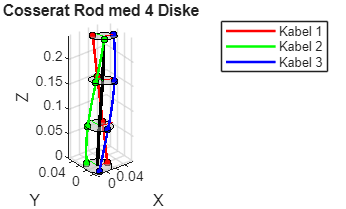


% Calculating deformations
origin=results(1,:);
deformations=-results+origin;
    
xdeformations=[deformations(:,1),deformations(:,4),deformations(:,7),deformations(:,10)];
%Plotting
plotting(s_out,y_out,params);

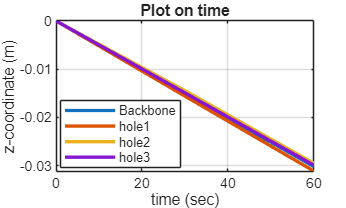

timePlotting(xdeformations,time);

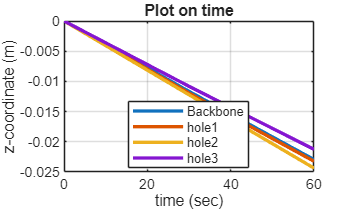

timePlotting([deformations(:,2),deformations(:,5),deformations(:,8),deformations(:,11)],time);

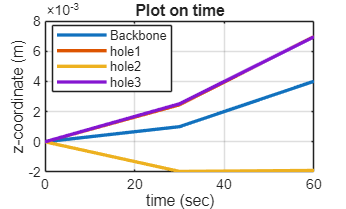

degreeTorsion = -4.2770

degreeTorsion_realsetup = 4.7788

timePlotting([deformations(:,3),deformations(:,6),deformations(:,9),deformations(:,12)],time);

function Error = shooting_bvp(X_guess, params)
    v0_guess = X_guess(1:3);
    u0_guess = X_guess(4:6);
    T0 = X_guess(7:9);
    
    % BC at base
    p0 = [0; 0; 0];
    q0 = [1; 0; 0; 0]; 
    l0 = [0; 0; 0];
    y0 = [p0; q0; v0_guess; u0_guess; l0; T0];

    % Integration
    [s_out, y_out] = ode45(@(s, y) cosserat_ode_explicit(s, y, params), [0, params.L], y0);
    
    % Values at s=L
    y_L = y_out(end, :)'; 
    qL = y_L(4:7);
    vL = y_L(8:10);
    uL = y_L(11:13);
    lL = y_L(14:16);
    TL = y_L(17:19);
    
    RL = quat2rotm(qL');
    
    % Calculating resulting forces and moments at tip
    [nL_tot, mL_tot] = calc_tip_wrench(vL, uL, TL, RL, params.L, params);
    
    % Calculate error, which converges to zero
    error_n = nL_tot;
    error_m = mL_tot;

    k=(pi*params.tendonD^2)/4*params.Kt./lL; % Spring constant of tendon
    gap =params.l_cmd - lL+T0./k; 
    error_l=sqrt(T0.^2+gap.^2)-gap-T0;
    
    Error = [error_n; error_m; error_l];
end

function dyds = cosserat_ode_explicit(s, y, params)
    p = y(1:3);
    q = y(4:7);
    v = y(8:10);
    u = y(11:13);
    l = y(14:16);
    T = y(17:19);

    R = quat2rotm(q');
    u_hat = skew(u);
    v_hat = skew(v);

    % System matrices
    A_mat = zeros(3,3); B_mat = zeros(3,3); 
    G_mat = zeros(3,3); H_mat = zeros(3,3);
    a_vec = zeros(3,1); b_vec = zeros(3,1);

    dpds = R * v; 
    dqds = quat_derivative(q, u);

    ncables = params.ncables;
    dlds = zeros(ncables, 1);
    dTds = zeros(ncables, 1);
    sum_f_fric_b = zeros(ncables,1);
    sum_l_fric_b = zeros(ncables,1);

    % Calculating cable length and tension
    for i = 1:ncables
        r = offset(s, i, params);
        r_hat = skew(r);
        
        drds = diff_offset_helix(s, i, params.d, params.pitch);
        ddrdds = -params.pitch^2 * r;
        
        % Tendon local tangent (dp_i^b)
        dp_b = u_hat * r + drds + v; 
        dp_b_hat = skew(dp_b);
        norm_dp_b = norm(dp_b);
        
        % System matrices
        Ai = -T(i) * (dp_b_hat^2) / (norm_dp_b^3);
        Bi = r_hat * Ai;
        
        A_mat = A_mat + Ai;
        B_mat = B_mat + Bi;
        G_mat = G_mat - Ai * r_hat;
        H_mat = H_mat - Bi * r_hat;
        
        ai = Ai * (u_hat * dp_b + u_hat * drds + ddrdds);
        bi = r_hat * ai;
        
        a_vec = a_vec + ai;
        b_vec = b_vec + bi;
        
        % Friction is a simplification in the length and tension
        dcable_dir = u_hat * drds + ddrdds; % ignoring u' and v' here
        kappa = norm(cross(dp_b, dcable_dir)) / (norm_dp_b^3);
        
        dlds(i) = norm_dp_b;
        dTds(i) = -params.mu * T(i) * kappa * dlds(i);

        % Force
        f_fric_b = dTds(i) * (dp_b / norm_dp_b);
        l_fric_b = cross(r, f_fric_b); % Moment by friction
        
        sum_f_fric_b = sum_f_fric_b + f_fric_b;
        sum_l_fric_b = sum_l_fric_b + l_fric_b;
    end

    % Gravity
    f_e = params.rho * params.A * params.g_world; 
    l_e = [0; 0; 0];
    f_e_b = R' * f_e + sum_f_fric_b;
    l_e_b = R' * l_e + sum_l_fric_b;

    % Reference for a straight rod
    v0_star = [0; 0; 1]; u0_star = [0; 0; 0];
    dv_star = [0; 0; 0]; du_star = [0; 0; 0];

    % C and d vectors
    c_vec = params.Kbt * du_star - u_hat * params.Kbt * (u - u0_star) ...
          - v_hat * params.Kse * (v - v0_star) - l_e_b - b_vec;
    d_vec = params.Kse * dv_star - u_hat * params.Kse * (v - v0_star) ...
          - f_e_b - a_vec;
     % l_e_b and f_e_b is already in the local frame

    % Solving linear system
    LHS = [params.Kse + A_mat, G_mat; 
           B_mat, params.Kbt + H_mat];
    RHS = [d_vec; c_vec];

    x_sol = LHS \ RHS;
    dvds = x_sol(1:3);
    duds = x_sol(4:6);

    dyds = [dpds; dqds; dvds; duds; dlds; dTds];
end

function [n_tot, m_tot] = calc_tip_wrench(v, u, T, R, s, params)
    % Calculating resulting forces at tip
    v0 = [0; 0; 1]; u0 = [0; 0; 0];
    
    n_backbone = R * params.Kse * (v - v0);
    m_backbone = R * params.Kbt * (u - u0);
    
    sum_n_cable = [0; 0; 0];
    sum_m_cable = [0; 0; 0];
    
    for i = 1:params.ncables
        r = offset(s, i, params);
        drds = diff_offset_helix(s, i, params.d, params.pitch);
        dp_b = v + cross(u, r) + drds;
        t_i = R * (dp_b / norm(dp_b));
        
        F_cable = -T(i) * t_i;
        sum_n_cable = sum_n_cable - F_cable;
        sum_m_cable = sum_m_cable - cross(R * r, F_cable);
    end
    
    n_tot = n_backbone + sum_n_cable;
    m_tot = m_backbone + sum_m_cable;
end

function rho=offset(s,i, params)
    alpha = [0, 2*pi/3, 4*pi/3];
    psi=params.beta*(s/params.L) + alpha(i);
    
    a_eff = 0.0015;  % hole radius, assuming negligible tendon radius
    mid=0.00125; %Midpoint of connection
    r_eff = params.d;

    rho = [r_eff*cos(psi); r_eff*sin(psi); 0];
end

function dr=diff_offset_helix(s,j,d,pitch)
    %Function to calculate the local position of the tendons.
    alpha = [0, 2*pi/3, 4*pi/3];
    phi=alpha(j)+pitch*s;
    
    dr=[-pitch*d*sin(phi); pitch*d*cos(phi); 0];
end

function theta=torsion_from_endpoint(P0, c0, P1, c1)
    %c0 - Original backbone position, c1 - Final backbone position
    %P0 - Original tendon position, P1 - Final tendon position
    
    %Radial vectors from backbone centerline to tendon hole
    r0=P0 - c0;
    r1=P1 - c1;
    
    %Normalize tangents
    t0=c0/norm(c0);
    t1=c1/norm(c1);
    
    %Remove any component along the tangent
    r0=r0-t0*dot(t0, r0);
    r1=r1-t1*dot(t1, r1);
    
    r0=r0/norm(r0);
    r1=r1/norm(r1);
    
    %Minimal rotation taking t0 to t1
    A=rotation_between_vectors(t0, t1);
    
    %Transport initial radial vector into the final normal plane
    r0_transported=A*r0;
    
    %Signed torsion angle about final tangent
    theta = atan2(dot(t1, cross(r0_transported, r1)), dot(r0_transported, r1));
end

function R=rotation_between_vectors(a, b)
    a=a/norm(a);
    b=b/norm(b);
    
    v=cross(a, b);
    c=dot(a, b);
    
    if norm(v)<1e-12
        if c>0
            R=eye(3);
        else
            %180 degree rotation: choose any axis perpendicular to a
            tmp=[1; 0; 0];
            if abs(dot(tmp, a))>0.9
                tmp=[0; 1; 0];
            end
            v=cross(a, tmp);
            v=v/norm(v);
            R=-eye(3)+2*(v*v.');
        end
        return;
    end
    vx=skew(v);
    R=eye(3)+vx+vx*vx*((1-c)/(norm(v)^2));
end

function A_skew=skew(a)
    % a is a 3x1 column vector
    % A_hat is the skewsymmetric matrix
    A_skew=[0, -a(3), a(2); a(3), 0, -a(1); -a(2), a(1), 0];
end

function dq = quat_derivative(q, omega)
    % q: [w; x; y; z]
    % omega: [wx; wy; wz] - angular velocity
    q = q / norm(q);
    Q = [ 0,      -omega(1), -omega(2), -omega(3);
          omega(1),  0,         omega(3), -omega(2);
          omega(2), -omega(3),  0,         omega(1);
          omega(3),  omega(2), -omega(1),  0 ];
      
    dq = 0.5 * Q * q;
end

function plotting(s,Y_out,params)
    % Disk parameters
    num_disks = params.nseg+1;
    s_disks = (linspace(0, params.L, num_disks)); % Points along s
    disk_radius = params.diskRadius;
    
    % Plot Backbone
    figure;
    plot3(Y_out(:,1), Y_out(:,2), Y_out(:,3), 'k-', 'LineWidth', 2); hold on;
    grid on; axis equal;
    xlabel('X'); ylabel('Y'); zlabel('Z');
    title('Cosserat Rod with 4 disks');
    
    % Plot Disks
    for i = 1:num_disks
        % Finding the row in the ODE-output that is closest to s_disk(i)
        [~, idx] = min(abs(s - s_disks(i)));
        
        % Get position and orientation
        r_disk = Y_out(idx, 1:3)';
        q_disk = Y_out(idx, 4:7);
        q_disk = q_disk / norm(q_disk);
        R = quat2rotm(q_disk); 
        
        % Making a circle in the local coordinates (xy-planet)
        theta_circ = linspace(0, 2*pi, 30);
        circle_local = [disk_radius * cos(theta_circ); 
                        disk_radius * sin(theta_circ); 
                        zeros(1, 30)];
        
        % Transform circle to globla position and orientation
        circle_global = R * circle_local + r_disk;
        
        % Draw disk
        fill3(circle_global(1,:), circle_global(2,:), circle_global(3,:), ...
              [0.7 0.7 0.7], 'FaceAlpha', 0.5, 'EdgeColor', 'k');
          
        % Local axis
        axis_len = disk_radius * 1.2;
        x_axis = R * [axis_len; 0; 0];
        y_axis = R * [0; axis_len; 0];
        line([r_disk(1) r_disk(1)+x_axis(1)], [r_disk(2) r_disk(2)+x_axis(2)], [r_disk(3) r_disk(3)+x_axis(3)], 'Color', 'r');
        line([r_disk(1) r_disk(1)+y_axis(1)], [r_disk(2) r_disk(2)+y_axis(2)], [r_disk(3) r_disk(3)+y_axis(3)], 'Color', 'g');
    end
    
    num_points = size(Y_out, 1); % Number of points
    cable_colors = {'r', 'g', 'b'};
    labels = {'Tendon 1', 'Tendon 2', 'Tendon 3'};
    
    % Looping over the cables
    for k = 1:3
        cable_pos_global = zeros(3, num_points);
        
        for i = 1:num_points
            current_s = s(i);
            r_backbone = Y_out(i, 1:3)';
            q = Y_out(i, 4:7);
            q = q / norm(q);
            R = quat2rotm(q);
            r=offset(current_s,k,params);
            cable_pos_global(:, i) = r_backbone + R * r;
        end
        
        % Plotting cable as a line, with points at the disk holes
        cable_h(k) = plot3(cable_pos_global(1,:), cable_pos_global(2,:), cable_pos_global(3,:), ...
              'Color', cable_colors{k}, 'LineWidth', 1.5, 'DisplayName', labels{k});
        for j = 1:num_disks
            [~, idx] = min(abs(s - s_disks(j)));
            plot3(cable_pos_global(1,idx), cable_pos_global(2,idx), cable_pos_global(3,idx), ...
                  'ko', 'MarkerFaceColor', cable_colors{k}, 'MarkerSize', 4, 'HandleVisibility', 'off');
        end
    end
    
    legend(cable_h, 'Location', 'northeastoutside');
    hold off;
    view(3); % 3D
end

function timePlotting(result,t)
    figure;
    plot(t, result(:,1), 'LineWidth', 2); 
    hold on; % Keep the first plot on the axes
    plot(t, result(:,2), 'LineWidth', 2);
    plot(t, result(:,3), 'LineWidth', 2);
    plot(t, result(:,4), 'LineWidth', 2);
    hold off;
    
    grid on;
    title('Plot on time');
    xlabel('time (sec)');
    ylabel('z-coordinate (m)');
    legend('Backbone', 'hole1', 'hole2', 'hole3', 'Location', 'best');
end
